# IMPORT DATA

close all
clc
clear all

dir = pwd;
wind_data = readtable(strcat(dir, '\Data\Wind_data.csv')).WindSpeed_m_s_;    %already access the table

Remove NaN from data

wind_data = wind_data(~isnan(wind_data));

## PDF ANALYSYS

Calculate number of bins to use with Sturges' formula

n_bins = ceil(1 + log2(length(wind_data)))

n_bins = 18

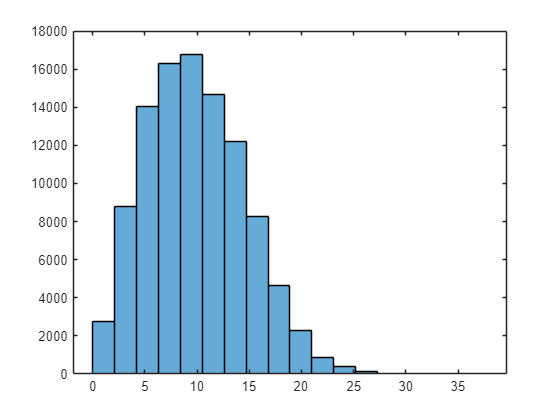


histogram(wind_data, n_bins)

Now we can fit the weibull distribution. No confidence interval is specified so it will be assumed to 95%

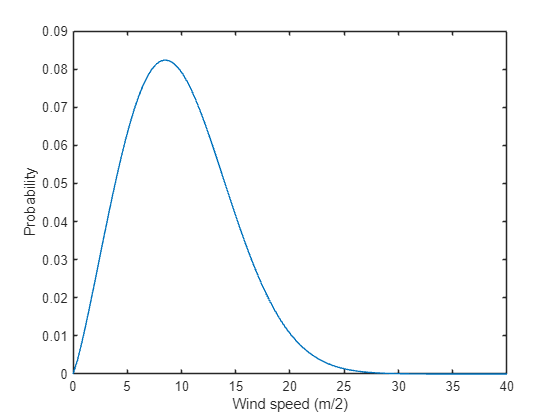

weibull_coeff = wblfit(wind_data);

x = linspace(0, 40);
plot(x, wblpdf(x, weibull_coeff(1), weibull_coeff(2)))
xlabel('Wind speed (m/2)')
ylabel('Probability')

## Stall regulated turbine

Constant speed, no pitch control.

Find the proper rotation speed.

Calculate 